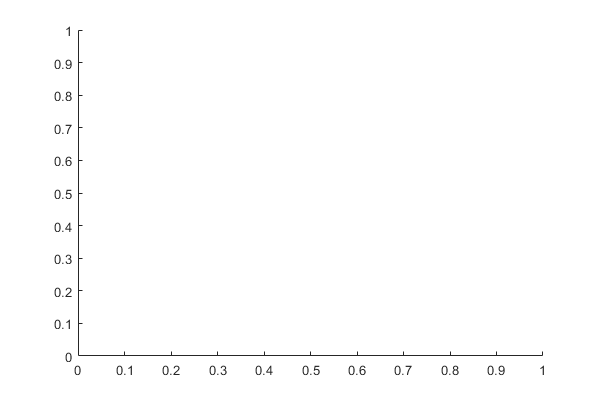


% thetas=calctheta(200,200,0)

PP1x = [];
PP1y = [];
PP2x = [];
PP2y = [];
PP3x = [];
PP3y = [];
Xc=[];
Yc=[];

for x = -150:2:600
    for y = -150:2:600
        for alpha = 0
            try
                k=calctheta(x,y,alpha,1);
%                 drawnow
%                 pause(0.2)
                PP1x(end+1)=[k(1,1)];
                PP1y(end+1)=[k(2,1)];
                PP2x(end+1)=[k(1,2)];
                PP2y(end+1)=[k(2,2)];
                PP3x(end+1)=[k(1,3)];
                PP3y(end+1)=[k(2,3)];
                Xc(end+1)=[x];
                Yc(end+1)=[y];

            catch ME
                
            end
        end
    end
end

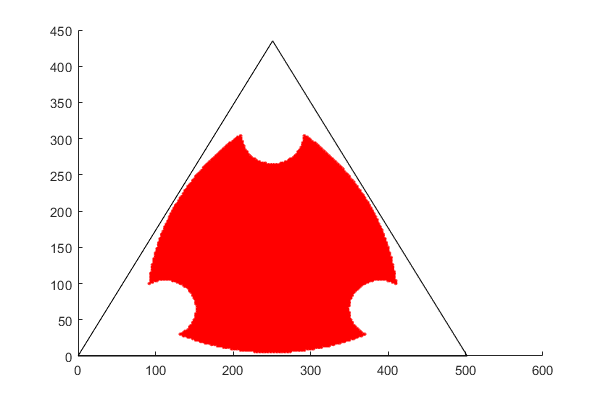

Rbase =290;
basex = [0 sqrt(3)*Rbase sqrt(3)*Rbase/2 0];
basey = [0 0 3/2*Rbase 0];

% hold on
% plot(basex,basey,"Color",'black')
% plot(PP1x,PP1y,'.',"Color",'b')
% plot(PP2x,PP2y,'.',"Color",'g')
% plot(PP3x,PP3y,'.',"Color",'r')
% hold off

hold on
plot(basex,basey,"Color",'black')
plot(Xc,Yc,'.',"Color",'r')
hold off